# **Lab 7: Face recognition using LDAs**

In this lab, we will employ LDA and SVM to identify the faces from different people.

We will use the ORL database, available on AT&T’s web site, as in previous labs. This database contains photographs showing the faces of 40 people (s1, s2, . . . , s40). Each one of them was photographed 10 times. These photos are stored as images in levels of grey with 112x92 pixels. The data has been split in two parts: train and test. For each person, we use the first 9 photographs for training and the last photograph for test. 

1. Load the training and the testing data (separately) and change each (d1 = 112) x (d2 = 92) photograph into a vector; 

% You can create a function on the form: 
% [trainingdata,testingdata]=loadImagesLab();
clc; 
clear all; 
close all;

data1 = 'orl_faces/Train/';
data2 =  'orl_faces/Test/';
matrix_train = []; 
matrix_test = [];
for path = 1: length(dir([data1,'s*']))
    for num = 1 : 9
        mat = imread([data1 's' mat2str(path) '/' mat2str(num) '.pgm' ]);
        mat2 = reshape(mat, [10304 1]);
        matrix_train = cat(2, matrix_train,  mat2);
    end
    
    % then use then tenth for the testing matrix
    num = 10;
    mat = imread([data2 's' mat2str(path) '/' mat2str(num) '.pgm' ]);
    mat2 = reshape(mat, [10304 1]);
    matrix_test = cat(2, matrix_test,  mat2);
end

**Classification using LDA**

Apply LDA to the **training** set. Follow these steps: 

2. Estimate the between class covariance and within class covariance. Then, use them to estimate the LDA matrix *V *that solves the following *generalized *Eigen problem 

*Sb*.*v *= l.*Sw*.*v *(use the eigs Matlab function [V, D]=eigs( *S**B* , *S**w* , L-1) to compute the eigenvectors), where *S**B *contains the between class scatter and *S**w*, the within class scatter of the training images feature vectors (you can use PCA weights as features for training and testing). Remember that if you have *L *different classes, LDA will provide *L-1 *non-zero eigenvalues. 

%You can create several functions on the form:
% [TrainingPCA,TestingPCA]=PCAlab(trainingdata,testingdata,PCAdimension);
% [V,D,TrainingLDA,TestingLDA]=LDAlab(TrainingPCA,TestingPCA,LDAdimension);

% TrainingPCA
PCAdimension = 50;
avg = mean(matrix_train, 2);%mean
center = double(matrix_train) - avg;%centered
corr = corrcoef(center');%corr
[TrainPCA, ~, ~] = eigs(corr, PCAdimension);%TrainingPCA
d1 = double(matrix_train)-avg;
e1 = TrainPCA;
TrainingPCA = e1'*d1; %PCA weights of train

% TestingPCA
d1 = double(matrix_test)-avg;
TestingPCA = e1'*d1; %PCA weights of test

% Between class scatter Sb
Sb  = 0;
m1 = mean(TrainingPCA,2); % mean of all the rows
len = length(dir([data1,'s*'])); 
Nk = 9; % scalar
for k = 1 : len
    mk = mean(TrainingPCA(:,(9*k-8):9*k), 2); % mean of rows,mk in equation
    Sb = Sb + Nk*(mk-m1)*(mk-m1)'; %Sb
end

% Within-class scatter Sw
Sw = 0;
for k = 1 : len
    mk = mean(TrainingPCA(:,(9*k-8):9*k)); % mean of columns
    for i = 1 : Nk
        xik = double(TrainingPCA(:,9*k-9+i ));% xik in equation
        Sw = Sw + (xik-mk)*(xik-mk)'; %Sw
    end
end

% eig of V and D
L = 40;
C = 9;
[V, D] = eigs(Sb, Sw, L-1); % get eig, here L = 40 so L -1 as input 3
m1 = cell(1,L);
for i=1:40 %calculate the train and test LDA
    w_p(:,C*(i-1)+1:C*i) = (V'*TrainingPCA(:,1+(i-1)*9:9*i));
    m_i = mean(w_p(:,C*(i-1)+1:C*i),2);
    m_i = m_i./norm(m_i,2);
    m1{i} = m_i;
end
m1= cell2mat(m1);
w_t = cell(1,L);
for i=1:40
    w_p_t = (V' * TestingPCA(:,i));
    w_t{i} = w_p_t;
end
TrainingLDA = w_p; 
TestingLDA = cell2mat(w_t);

3. Check the identity corresponding to each photograph in the **testing** set by determining its LDA projection (with dimension 10, 20, 30 and 39) employing the LDA matrix obtaining with the training data and then comparing the distances of this projection with respect to all projections in the training data. For each test category find the closest category in the test. Report your accuracy

%You can create several functions on the form:
% [LDAresults]=distancesLab(TrainingLDA,TestingLDA);
% Also, you can generate figures representing the accuracy as a function of the PCAdimension and LDAdimension
acc = zeros(1,4); 
count = 1;
for i = [10, 20, 30, 39] % dimension
    [V,~] = eigs(Sb, Sw, i-1);
    proj_test  = V' * TestingPCA; % projection
    proj_train = V' * TrainingPCA;
    dist = pdist2(proj_train', proj_test','euclidean'); % find distance
    [~,dist_min] = min(dist,[],1); % get min dist
    dist_img = ceil(dist_min/9);    
    acc(count) = sum(dist_img == (1:40))/size(TestingPCA,2);% accuracy
    count = count+1;
end
disp('the four accuracy is');disp(acc);

the four accuracy is
    0.9000    0.9500    0.9500    0.9750



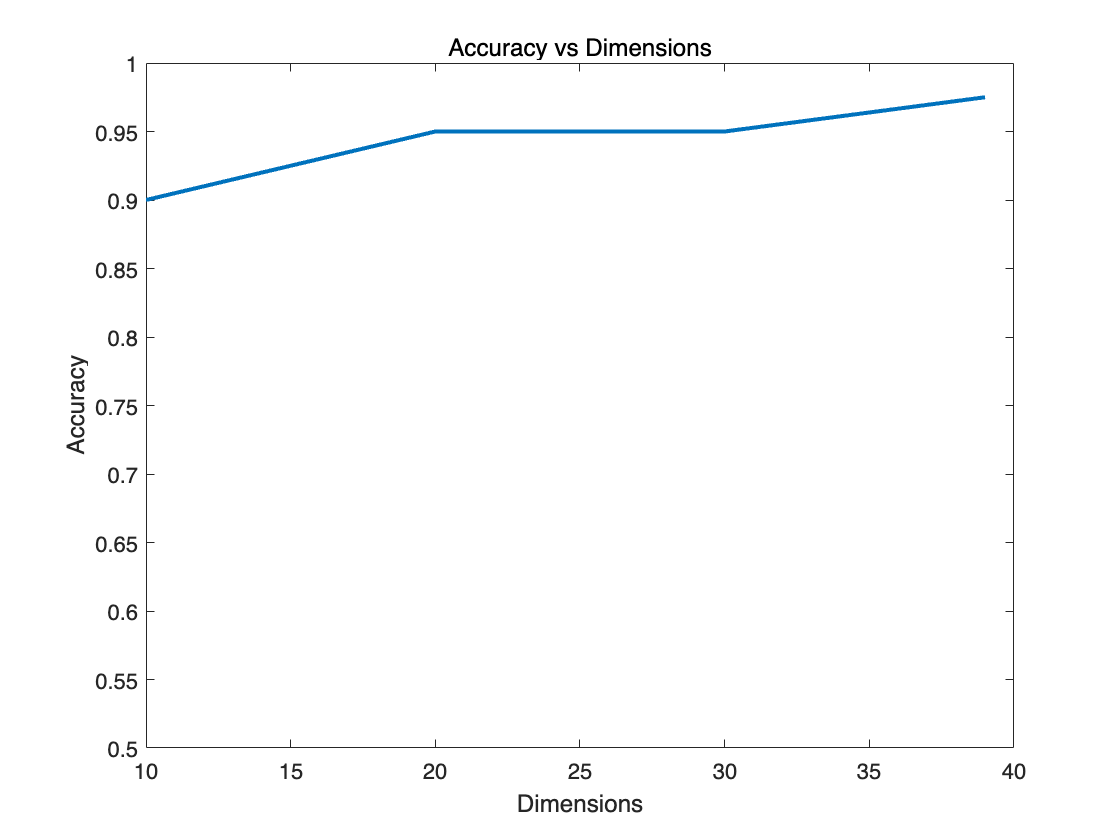

y = [10,20,30,39];
plot(y,acc,'linewidth',2);
title("Accuracy vs Dimensions");
xlabel('Dimensions');
ylabel("Accuracy");
ylim([0.5 1]);

**Optional: Classification using LDA+SVM (+5 extra points)**

4. Using the LDA projections of the training faces, train a SVM model to identify the different people. Therefore, resulting model will include 40 classes. Then, test the model using the LDA projections of the testing faces. Use the Matlab function or LIBSVM library to do the binary classification. Examples can be found in [https://www.mathworks.com/help/stats/support-vector-machine-classification.html](https://www.mathworks.com/help/stats/support-vector-machine-classification.html) for Matlab.  Play with different C values and kernel functions and see how they influence the result. Report your best accuracy and settings include dimension, C value, kernel function you used. 

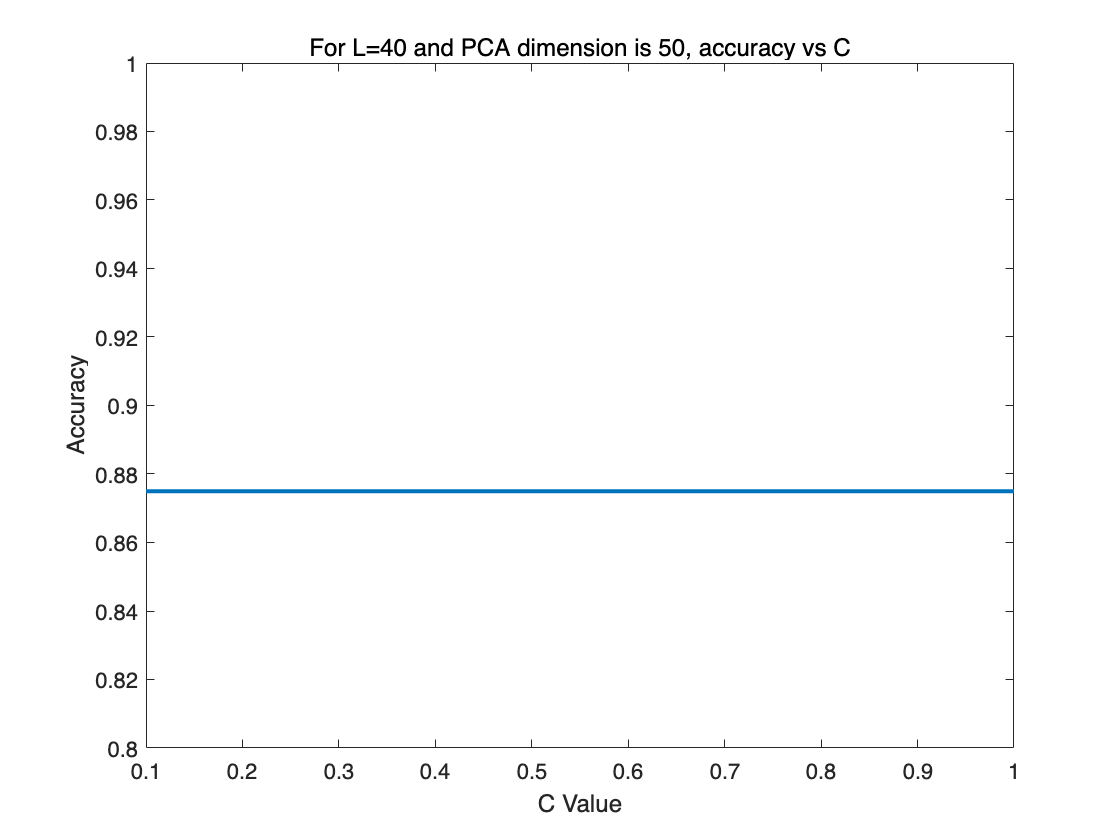

% [SVMresults]=SVMlab(TrainingLDA,TestingLDA);
% You can generate figures representing the accuracy as a function of the PCAdimension and LDAdimension and C
[SVMresults1]=SVMlab(TrainingLDA,TestingLDA,'linear', 0.1);% apply svm use the LDA before
[SVMresults3]=SVMlab(TrainingLDA,TestingLDA,'linear', 0.3);
[SVMresults5]=SVMlab(TrainingLDA,TestingLDA,'linear', 0.5);
[SVMresults7]=SVMlab(TrainingLDA,TestingLDA,'linear', 0.7);
[SVMresults9]=SVMlab(TrainingLDA,TestingLDA,'linear', 0.9);
[SVMresults10]=SVMlab(TrainingLDA,TestingLDA,'linear', 1);

d1=[0.1 0.3 0.5 0.7 0.9 1];
y=[SVMresults1 SVMresults3 SVMresults5 SVMresults7 SVMresults9 SVMresults10];
plot(d1,y,'linewidth',2);
xlabel('C Value');
ylabel('Accuracy');
ylim([0.8 1]);
title('For L=40 and PCA dimension is 50, accuracy vs C');

**Provide a report in *****pdf *****format explaining your results (you can provide a pdf of this script including graphics and results).**

**NOTES:**

- The suggested functions are just a guide. You can create them or not. Also, you can add or remove input/output parameters as needed.

- Between class scatter:


$$S_B=\sum_{k=1}^K N_k(m_{k}-m)(m_{k}-m)^T$$


where *K* is the total number of classes, $N_k$ is the number of observations on class *k*, $m_{k}$is the mean of vectors of class *k* and $m$ is the mean of all the vectors (global mean).

- Within-class scatter:

 
$$S_w=\sum_{k=1}^K\sum_{i=1}^{N_k}(x_{ik}-m_k)(x_{ik}-m_k)^T$$


where $x_{ik}$ is the $i^{th}$ observation of class *k*.

-      PCA projection is recommended to obtain the features to be used to train the LDA matrix in order to avoid singularity problems. If PCA is not used over the original data, the number of features per observation (10304) will be much larger than the number of observations (360) and the covariance matrices will not have full rank and will not be invertible.